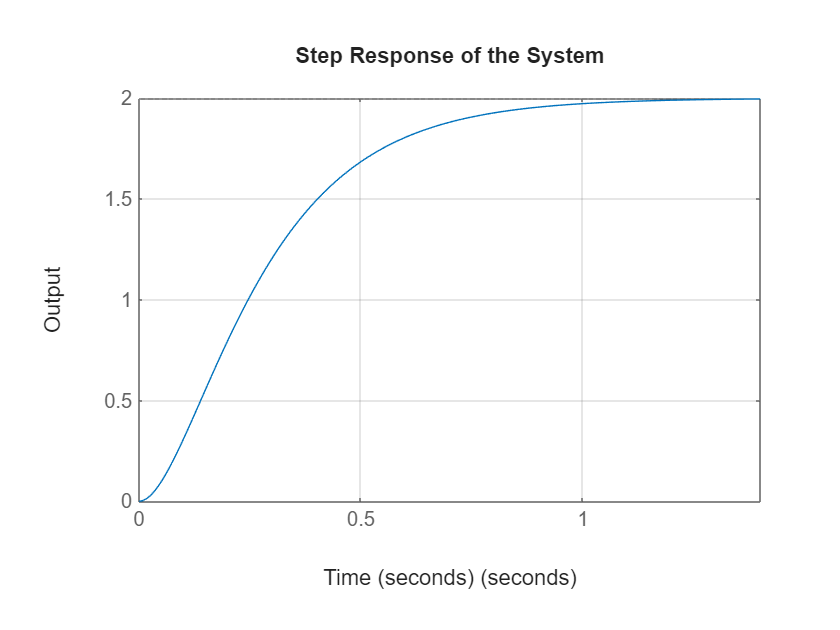

%%Assignment 2

%%Problem1:Basic plant response analysis
num=[100];
den=[1 15 50];
G1=tf(num,den);
G=tf(num,den);
%a)open loop analysis
% Plot step response
figure
step(G1)
grid on
title('Step Response of the System')
xlabel('Time (seconds)')
ylabel('Output')

%Calculate and report: rise time, settling time, peak overshoot, and steady-state error
info = stepinfo(G1);

% Display results
fprintf('Rise Time: %.3f seconds\n', info.RiseTime);

Rise Time: 0.518 seconds


fprintf('Settling Time: %.3f seconds\n', info.SettlingTime);

Settling Time: 0.920 seconds


fprintf('Peak Overshoot: %.2f %%\n', info.Overshoot);

Peak Overshoot: 0.00 %



%% Steady-State Error Calculation

% Obtain step response data
[y, t] = step(G1);

% Final value of output
steady_state_value = y(end);

% Steady-state error for unit step input
ess1 = 1 - steady_state_value;

fprintf('Steady-State Error: %.4f\n', ess1);

Steady-State Error: -0.9931



%% Performance Summary Table

Performance_Table1 = table( ...
    info.RiseTime, ...
    info.SettlingTime, ...
    info.Overshoot, ...
    ess, ...
    'VariableNames', {'RiseTime_s', 'SettlingTime_s', 'Overshoot_percent', 'SteadyStateError'} );

Performance_Table1

Performance_Table1 = 1×4 table
    RiseTime_s    SettlingTime_s    Overshoot_percent    SteadyStateError
    __________    ______________    _________________    ________________

     0.51802         0.92005                0                -0.99305    


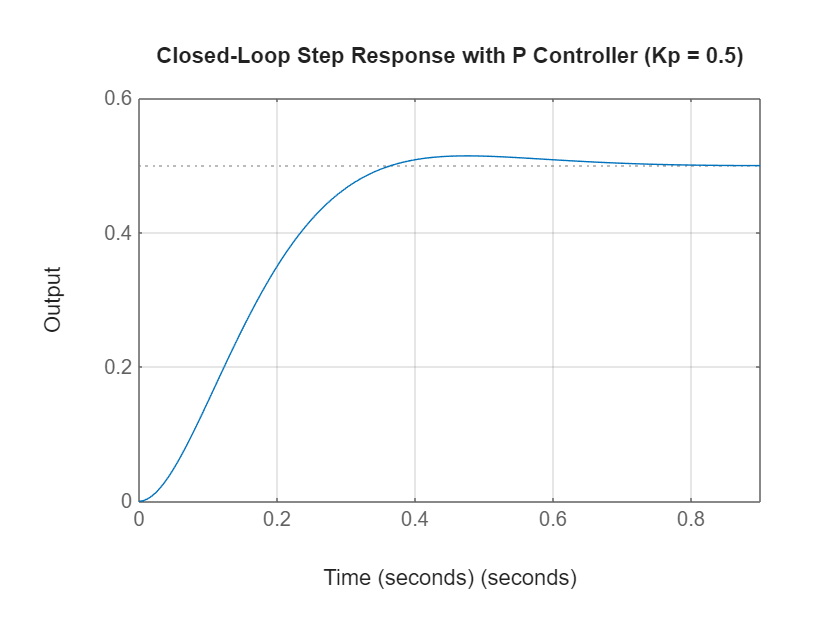




%%b)proportional controller
kp=0.5;
C1 = kp;
% Unity feedback closed-loop system
G_cl1 = feedback(C1*G1, 1);

%% Step Response of Closed-Loop System
figure
step(G_cl1)
grid on
title('Closed-Loop Step Response with P Controller (Kp = 0.5)')
xlabel('Time (seconds)')
ylabel('Output')


%% Performance Metrics

% Step response information
info_p = stepinfo(G_cl1);

fprintf('Rise Time: %.3f seconds\n', info_p.RiseTime);

Rise Time: 0.229 seconds


fprintf('Settling Time: %.3f seconds\n', info_p.SettlingTime);

Settling Time: 0.574 seconds


fprintf('Peak Overshoot: %.2f %%\n', info_p.Overshoot);

Peak Overshoot: 2.84 %



%% Steady-State Error Calculation

% Step response data
[y, t] = step(G_cl1);

% Final output value
steady_state_value = y(end);

% Steady-state error for unit step input
ess_p = 1 - steady_state_value;

fprintf('Steady-State Error: %.4f\n', ess_p);

Steady-State Error: 0.5001



%% Performance Summary Table

Performance_Table_P = table( ...
    info_p.RiseTime, ...
    info_p.SettlingTime, ...
    info_p.Overshoot, ...
    ess_p, ...
    'VariableNames', {'RiseTime_s', 'SettlingTime_s', 'Overshoot_percent', 'SteadyStateError'} );

Performance_Table_P

Performance_Table_P = 1×4 table
    RiseTime_s    SettlingTime_s    Overshoot_percent    SteadyStateError
    __________    ______________    _________________    ________________

     0.22884         0.57426             2.8369              0.50006     


Steady state error exist with P controller because when the error becomes zero the output also becomes zero.

%c)PI controller
Kp = 0.5;
Ki = 1.5;


% P-only controller (for comparison)
C_P = Kp;

% PI controller
C_PI = pid(Kp, Ki);

%% Closed-Loop Systems
G_cl_P = feedback(C_P * G1, 1);
G_cl_PI = feedback(C_PI * G1, 1);

%% Step Response Comparison

figure
step(G_cl_P, G_cl_PI)
grid on
legend('P Controller', 'PI Controller')
title('Step Response Comparison: P vs PI Controller')
xlabel('Time (seconds)')
ylabel('Output')


%% Performance Metrics

% Step response characteristics
info_P  = stepinfo(G_cl_P);
info_PI = stepinfo(G_cl_PI);

%% Steady-State Error Calculation

% P Controller steady-state error
[yP, tP] = step(G_cl_P);
ess_P = 1 - yP(end);

% PI Controller steady-state error
[yPI, tPI] = step(G_cl_PI);
ess_PI = 1 - yPI(end);

%% Performance Comparison Table

Performance_Comparison = table( ...
    info_P.RiseTime,  info_PI.RiseTime, ...
    info_P.SettlingTime, info_PI.SettlingTime, ...
    info_P.Overshoot, info_PI.Overshoot, ...
    ess_P, ess_PI, ...
    'VariableNames', {'RiseTime_P', 'RiseTime_PI', ...
                      'SettlingTime_P', 'SettlingTime_PI', ...
                      'Overshoot_P', 'Overshoot_PI', ...
                      'SteadyStateError_P', 'SteadyStateError_PI'} );

Performance_Comparison

Performance_Comparison = 1×8 table
    RiseTime_P    RiseTime_PI    SettlingTime_P    SettlingTime_PI    Overshoot_P    Overshoot_PI    SteadyStateError_P    SteadyStateError_PI
    __________    ___________    ______________    _______________    ___________    ____________    __________________    ___________________

     0.22884        0.6278          0.57426            1.5377           2.8369            0               0.50006               0.0043289     


with integral action eventhough the instantenous error had become zero the integrated value of past errors(memory) prevented the output from becoming zero.

%%d)PID controller
%the following constants were obtained by solving with given 
%constraints manually
Kp = 1.2;
Ki = 2.5;
Kd = 0.3;

% Define PID controller
C_PID = pid(Kp, Ki, Kd);

%% Closed-Loop System with PID Controller

G_cl_PID = feedback(C_PID * G1, 1);

%% Step Response of Tuned PID System

figure
step(G_cl_PID)
grid on
title('Closed-Loop Step Response with Tuned PID Controller')
xlabel('Time (seconds)')
ylabel('Output')

%% Performance Metrics

info_PID = stepinfo(G_cl_PID);

fprintf('Rise Time: %.3f seconds\n', info_PID.RiseTime);

Rise Time: 0.774 seconds


fprintf('Settling Time: %.3f seconds\n', info_PID.SettlingTime);

Settling Time: 1.324 seconds


fprintf('Overshoot: %.2f %%\n', info_PID.Overshoot);

Overshoot: 0.35 %



%% Steady-State Error Calculation

[yPID, tPID] = step(G_cl_PID);
ess_PID = 1 - yPID(end);

fprintf('Steady-State Error: %.5f\n', ess_PID);

Steady-State Error: -0.00229



%% Annotate Plot with Performance Metrics

hold on
text(0.6, 0.2, sprintf( ...
    'Rise Time = %.2f s\nSettling Time = %.2f s\nOvershoot = %.2f %%\nSteady-State Error = %.4f', ...
    info_PID.RiseTime, ...
    info_PID.SettlingTime, ...
    info_PID.Overshoot, ...
    ess_PID), ...
    'FontSize', 10, 'BackgroundColor', 'w')
hold off

%% Final PID Performance Table

PID_Performance = table( ...
    Kp, Ki, Kd, ...
    info_PID.RiseTime, ...
    info_PID.SettlingTime, ...
    info_PID.Overshoot, ...
    ess_PID, ...
    'VariableNames', {'Kp', 'Ki', 'Kd', ...
                      'RiseTime_s', 'SettlingTime_s', ...
                      'Overshoot_percent', 'SteadyStateError'} );

PID_Performance

PID_Performance = 1×7 table
    Kp     Ki     Kd     RiseTime_s    SettlingTime_s    Overshoot_percent    SteadyStateError
    ___    ___    ___    __________    ______________    _________________    ________________

    1.2    2.5    0.3     0.77448          1.324              0.35249            -0.0022909   


Problem 2: Complex Input Tracking

%%Problem 2: Complex Input Tracking

%%problem2 a)
dt=0.01;
t=0:dt:20;
r=zeros(size(t));
for i =1:length(t)
    if t(i)<5
        r(i)=1;
    elseif t(i)<10
        r(i)=1.5;
    elseif t(i)<15
        r(i)=0.8;
    else 
        r(i)=1.2;
    end
end
[y, t_out]=lsim(G_cl_PID,r,t);
figure
plot(t_out, r, 'k--', 'LineWidth', 1.5)
hold on
plot(t_out, y, 'b', 'LineWidth', 1.5)
grid on
xlabel('Time (seconds)')
ylabel('Amplitude')
title('Multi-Step Reference Tracking Using PID Controller')
legend('Reference Signal', 'System Output')
hold off

%% Tracking Error Calculation

% Tracking error
e = r - y;

%% Plot Tracking Error Over Time

figure
plot(t_out, e, 'r', 'LineWidth', 1.5)
grid on
xlabel('Time (seconds)')
ylabel('Tracking Error')
title('Tracking Error vs Time')


%problem2 b)

% Time vector
t = 0:0.01:20;   


% Ramp input: r(t) = 0.2t
r = 0.2 * t;

% PID gains
Kp = 1.2;
Ki = 2.5;
Kd = 0.3;

C_PID = pid(Kp, Ki, Kd);

% Closed-loop system
G_cl = feedback(C_PID * G, 1);

%% Simulate Response Using lsim()

[y, t_out] = lsim(G_cl, r, t);

%% Tracking Error Calculation

e = r - y;

%% Plot Reference, Output, and Error

figure
subplot(2,1,1)
plot(t_out, r, 'k--', 'LineWidth', 1.5)
hold on
plot(t_out, y, 'b', 'LineWidth', 1.5)
grid on
xlabel('Time (seconds)')
ylabel('Amplitude')
title('Ramp Input Tracking: Reference vs Output')
legend('Reference', 'Output')
hold off

subplot(2,1,2)
plot(t_out, e, 'r', 'LineWidth', 1.5)
grid on
xlabel('Time (seconds)')
ylabel('Tracking Error')
title('Tracking Error vs Time')


%% Steady-State Tracking Error

% Approximate steady-state error (near end of simulation)
ess_ramp = mean(e(end-100:end));

fprintf('Steady-State Tracking Error (Ramp Input): %.4f\n', ess_ramp);

Steady-State Tracking Error (Ramp Input): 0.1400


A ramp input represents a continuously increasing reference signal, which is more challenging to track than a step input.

Although the PID controller includes integral action, it may still exhibit steady-state tracking error for a ramp input due to limited system type and finite integral gain.

Perfect ramp tracking requires a higher system type or additional integrators in the control loop.

Excessive integral gain can reduce ramp error but may introduce instability or excessive overshoot.

%% (c) Sinusoidal Reference Tracking
t = 0:0.01:20;   

r = sin(0.5 * t);

% PID gains
Kp = 1.2;
Ki = 2.5;
Kd = 0.3;

C_PID = pid(Kp, Ki, Kd);

% Closed-loop system
G_cl = feedback(C_PID * G, 1);

%% Simulate System Response Using lsim()

[y, t_out] = lsim(G_cl, r, t);

%% Plot Tracking Performance

figure
plot(t_out, r, 'k--', 'LineWidth', 1.5)
hold on
plot(t_out, y, 'b', 'LineWidth', 1.5)
grid on
xlabel('Time (seconds)')
ylabel('Amplitude')
title('Sinusoidal Reference Tracking with PID Controller')
legend('Reference Signal', 'System Output')
hold off


%% Phase Lag Calculation

% Find peaks of reference and output
[~, locs_r] = findpeaks(r, t_out);

findpeaks requires Signal Processing Toolbox.

[~, locs_y] = findpeaks(y, t_out);

% Use first peak for phase lag estimation
phase_time_delay = locs_y(1) - locs_r(1);

% Convert time delay to phase lag (radians and degrees)
omega = 0.5;  % input frequency (rad/s)
phase_lag_rad = omega * phase_time_delay;
phase_lag_deg = rad2deg(phase_lag_rad);

fprintf('Phase Lag: %.4f radians (%.2f degrees)\n', ...
        phase_lag_rad, phase_lag_deg);

For sinusoidal reference tracking, phase lag and amplitude attenuation are key performance measures.

The proportional gain primarily affects the tracking amplitude, while the integral term has limited impact at higher frequencies.

The derivative term plays the most significant role in improving sinusoidal tracking by reducing phase lag and improving system responsiveness to rapidly changing signals.

Excessive derivative action, however, may amplify noise and should be used carefully.

%%Problem 3 

%% Plant Definition
num = 50;
den = [1 8 25 20];
G = tf(num, den);

% Discretization
Ts = 0.001;% small step for control simulation
Gd = c2d(G, Ts, 'zoh');

% Simulation time
t = 0:Ts:10;
N = length(t);

% Actuator limits
u_max = 10;
u_min = -10;
%% (a) PI Controller WITHOUT Anti-Windup

Kp = 5;
Ki = 8;

r = 5 * ones(1, N); 

% Preallocate
y = zeros(1, N);
u = zeros(1, N);
u_sat = zeros(1, N);
e = zeros(1, N);
integral = zeros(1, N);

x = zeros(size(Gd.A,1),1); % plant state
for k = 2:N
    % Error
    e(k) = r(k) - y(k-1);

    % Integrator (NO saturation awareness)
    integral(k) = integral(k-1) + e(k)*Ts;

    % Unsaturated control
    u(k) = Kp*e(k) + Ki*integral(k);

    % Actuator saturation
    u_sat(k) = max(min(u(k), u_max), u_min);

    % Plant update
    x = Gd.A*x + Gd.B*u_sat(k);
    y(k) = Gd.C*x;
end
figure
subplot(4,1,1)
plot(t, r, 'k--', t, y, 'b'), grid on
title('Reference vs Output (No Anti-Windup)')
ylabel('Output')

subplot(4,1,2)
plot(t, u, 'r--', t, u_sat, 'b'), grid on
ylabel('Control Signal')
legend('u (unsat)', 'u_{sat}')

subplot(4,1,3)
plot(t, integral), grid on
ylabel('Integral Term')

subplot(4,1,4)
plot(t, e), grid on
ylabel('Error'), xlabel('Time (s)')

During saturation, the control input is clipped while the integrator continues to accumulate error.

This causes excessive integral buildup, leading to large overshoot and long settling time once the actuator leaves saturation.

%% (b) PI Controller WITH Anti-Windup (Back-Calculation)

Kt = sqrt(Ki);

% Reset variables
y_aw = zeros(1, N);
u_aw = zeros(1, N);
u_sat_aw = zeros(1, N);
integral_aw = zeros(1, N);
e_aw = zeros(1, N);

x = zeros(size(Gd.A,1),1);
for k = 2:N
    e_aw(k) = r(k) - y_aw(k-1);

    % Unsaturated control
    u_aw(k) = Kp*e_aw(k) + Ki*integral_aw(k-1);

    % Saturation
    u_sat_aw(k) = max(min(u_aw(k), u_max), u_min);

    % Anti-windup correction
    integral_aw(k) = integral_aw(k-1) + ...
        ( e_aw(k) + (1/Kt)*(u_sat_aw(k) - u_aw(k)) ) * Ts;

    % Plant update
    x = Gd.A*x + Gd.B*u_sat_aw(k);
    y_aw(k) = Gd.C*x;
end
figure
plot(t, y, 'r--', t, y_aw, 'b', t, r, 'k:')
grid on
title('Anti-Windup Comparison')
legend('No Anti-Windup', 'With Anti-Windup', 'Reference')
info_no = stepinfo(y, t, r(1));
info_aw = stepinfo(y_aw, t, r(1));

sat_time_no = sum(abs(u) >= u_max)*Ts;
sat_time_aw = sum(abs(u_aw) >= u_max)*Ts;

Windup_Table = table( ...
    info_no.Overshoot, info_aw.Overshoot, ...
    info_no.SettlingTime, info_aw.SettlingTime, ...
    sat_time_no, sat_time_aw, ...
    'VariableNames', {'Overshoot_NoAW','Overshoot_AW', ...
                      'Settling_NoAW','Settling_AW', ...
                      'SatTime_NoAW','SatTime_AW'} );

Windup_Table
%% (c) Derivative Noise and Filtering

Kd = 2;
y_noisy = y_aw + 0.05*randn(size(y_aw));
d_raw = [0 diff(e_aw)/Ts];
u_d_raw = Kd * d_raw;
figure
subplot(2,1,1)
plot(t, u_d_raw), grid on
title('Unfiltered Derivative Control')

subplot(2,1,2)
plot(t, u_d_filt), grid on
title('Filtered Derivative Control')
std_raw = std(u_d_raw);
std_filt = std(u_d_filt);

fprintf('Derivative Std Dev (Raw): %.3f\n', std_raw);
fprintf('Derivative Std Dev (Filtered): %.3f\n', std_filt);
%% (d) Complex Trajectory Tracking

r = zeros(1,N);

for k = 1:N
    if t(k) < 2
        r(k) = 0.5*t(k);
    elseif t(k) < 4
        r(k) = 1;
    elseif t(k) < 8
        r(k) = 1 + 0.5*sin(2*pi*(t(k)-4));
    elseif t(k) < 10
        r(k) = 2;
    elseif t(k) < 15
        r(k) = 2 - 0.3*(t(k)-10);
    else
        r(k) = 0.5;
    end
end
e_track = r - y_aw;
e_rms = sqrt(mean(e_track.^2));
fprintf('RMS Tracking Error: %.4f\n', e_rms);
figure
subplot(3,1,1)
plot(t, r, 'k--', t, y_aw), grid on
title('Complex Trajectory Tracking')

subplot(3,1,2)
plot(t, e_track), grid on
ylabel('Tracking Error')

subplot(3,1,3)
plot(t, u_sat_aw), grid on
ylabel('Control'),

Anti-windup prevents excessive integral accumulation during actuator saturation, significantly reducing overshoot and settling time.

Derivative filtering reduces noise amplification while maintaining damping performance.

The complete PID controller successfully tracks complex trajectories while respecting actuator limits.

save _240898_sabeeh_Assignment2_smart_throttle_control

